%% 1. INICIALIZACIÓN, CARGA Y PREPARACIÓN DE DATOS 💾

% Limpia el espacio de trabajo y la ventana de comandos
clear; clc;

% --- Carga de Datos ---
filename = "C:/Users/Jesus Coss/Documents/analisis_proyectos/proy_Tarifa_Dinamica/9.DynamicPricing_ETN/9.DynamicPricing_ETN/PorCorreo.xlsx";
T = readtable(filename, 'VariableNamingRule', 'preserve');
disp(['Tabla cargada con ', num2str(size(T, 1)), ' filas.']);

Tabla cargada con 137061 filas.



% --- Aplicar filtro inicial ---
T = T(T.SBol_Vend > 1, :);
disp(['Tabla filtrada con ', num2str(size(T, 1)), ' filas.']);

Tabla filtrada con 87241 filas.



% --- Selección de Características (Desde la 4ta Columna hasta el final) ---
all_var_names = T.Properties.VariableNames;
% Selecciona los nombres de las columnas a partir de la 4ta posición
feature_vars = all_var_names(3:end); 
X_table = T(:, feature_vars); 

% Filtramos NaNs (valores faltantes) y convertimos a matriz numérica X
X_table = rmmissing(X_table);
X = table2array(X_table); 

disp('--- Características Seleccionadas para K-Means ---');

--- Características Seleccionadas para K-Means ---


disp(feature_vars);

    {'SBol_Vend'}    {'Prom_Pagado'}    {'Sum_Pagado'}    {'%_Promo'}    {'Prom_Horas_Ant'}    {'Venta_Ant'}    {'Recencia'}    {'PAGO_EFECTIVO'}    {'PAGO_TARJETA'}    {'DESC_ADULTO'}    {'DESC_DISCAPACIDAD'}    {'DESC_ESTUDIANTE'}    {'DESC_MENOR'}    {'DESC_PETFRIENDLY'}    {'DESC_PROFESOR'}    {'DESC_PROMOCION ESPECIAL'}    {'DESC_SENECTUD'}



fprintf('Matriz X inicial con %d filas y %d características.\n', size(X, 1), size(X, 2));

Matriz X inicial con 87241 filas y 17 características.



rng(1); % Fija la semilla para reproducibilidad


%% 2. ANÁLISIS DE COMPONENTES PRINCIPALES (PCA) 📉

% **Paso 1: Normalización de los Datos (Estandarización)**
% Es crucial para PCA que todas las variables tengan la misma escala.
X_norm = zscore(X);

% **Paso 2: Ejecutar PCA**
[coeff, score, latent] = pca(X_norm);

% **Paso 3: Determinar el número de Componentes (ej: mantener el 90% de la varianza)**
explained_variance = cumsum(latent) / sum(latent);
num_components = find(explained_variance >= 0.90, 1, 'first'); 

% Asegurarse de que el número de componentes no exceda el máximo y tenga al menos 2 para visualización.
if isempty(num_components) || num_components > size(X, 2)
    num_components = size(X, 2); % Usa el máximo si no alcanza el 90%
end

% **Paso 4: Reducción de dimensionalidad**
X_pca = score(:, 1:num_components); 

disp('--- Resultado PCA ---');

--- Resultado PCA ---


fprintf('Se usarán %d componentes principales (PC).\n', num_components);

Se usarán 10 componentes principales (PC).


fprintf('La nueva matriz X_pca tiene %d características.\n', size(X_pca, 2));

La nueva matriz X_pca tiene 10 características.



% Graficar la varianza explicada para la selección visual
figure;
pareto(latent);
title('Gráfico de Sedimento (Varianza Explicada por PC)');
xlabel('Componente Principal');
ylabel('Varianza Explicada');

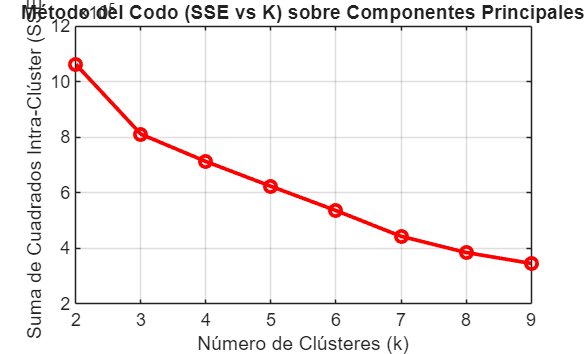




%% 3. PARÁMETROS DEL GRID SEARCH 🛠️

% Define los rangos de valores a probar
k_values = 2:9; % Probar K de 2 a 6
distances = {'sqeuclidean', 'cityblock', 'cosine'}; 
num_replicates = 10; % Mayor número para más estabilidad (menos riesgo de mínimos locales)

all_sse = zeros(length(k_values), 1);
best_overall_sse = Inf;
best_k = 0;
best_dist = '';


%% 4. MÉTODO DEL CODO (LOOP DE K) - BUCLE EXTERNO 🧮

idx_k = 1; 

for k = k_values
    % Usamos solo la distancia 'sqeuclidean' (estándar) para la curva del codo.
    [~, ~, sumd] = kmeans(X_pca, k, ... 
        'Distance', 'sqeuclidean', ...
        'Replicates', num_replicates);
    
    total_sse = sum(sumd);
    all_sse(idx_k) = total_sse;
    idx_k = idx_k + 1;
end

% Visualización del Codo
figure;
plot(k_values, all_sse, 'r-o', 'LineWidth', 2);
title('Método del Codo (SSE vs K) sobre Componentes Principales');
xlabel('Número de Clústeres (k)');
ylabel('Suma de Cuadrados Intra-Clúster (SSE)');
grid on;




%% 5. GRID SEARCH COMPLETO (K y DISTANCIA) 🔍

disp('Iniciando Grid Search completo sobre X_pca...');

Iniciando Grid Search completo sobre X_pca...



% Bucle anidado para probar todas las combinaciones de K y Distancia
for k = k_values
    for dist_idx = 1:length(distances)
        current_dist = distances{dist_idx};

        [~, ~, sumd] = kmeans(X_pca, k, ... 
            'Distance', current_dist, ...
            'Replicates', num_replicates);
        
        total_sse = sum(sumd);
        
        % Comprobar y actualizar el mejor modelo (buscamos el SSE más bajo)
        if total_sse < best_overall_sse
            best_overall_sse = total_sse;
            best_k = k;
            best_dist = current_dist;
        end
    end
end

disp('--- Resultado del Grid Search ---');

--- Resultado del Grid Search ---


fprintf('El mejor modelo (min SSE) es: K = %d, Distancia = %s, SSE = %.2f\n', best_k, best_dist, best_overall_sse);

El mejor modelo (min SSE) es: K = 9, Distancia = cosine, SSE = 8007.18





%% 6. MODELO FINAL Y VISUALIZACIÓN 🚀

% Re-ejecutar K-Means con los mejores parámetros encontrados
[final_idx, final_C] = kmeans(X_pca, best_k, ...
    'Distance', best_dist, ...
    'Replicates', num_replicates);

disp('Centroides Finales (C) en el espacio PCA:');

Centroides Finales (C) en el espacio PCA:


disp(final_C);

    0.5614   -0.2400    0.3563    0.1978   -0.1170    0.0937   -0.0044    0.0679   -0.3397    0.3147
   -0.6428    0.6032   -0.0520   -0.0335   -0.0107    0.0020   -0.0150   -0.0099   -0.0074   -0.0498
   -0.1976   -0.7043   -0.4167   -0.1986    0.0717   -0.0519   -0.1556   -0.0347   -0.2717   -0.1248
   -0.3230   -0.5987    0.2548    0.0947   -0.3130   -0.0895    0.0421   -0.0729    0.3988   -0.1239
    0.8754    0.2033    0.1134   -0.2669    0.0130   -0.0140   -0.0845   -0.0772    0.0978   -0.0177
    0.8451   -0.0407   -0.1948    0.4170   -0.0439    0.0554    0.0911    0.0701   -0.0103    0.0751
   -0.2616    0.3049   -0.3728   -0.2334   -0.2916    0.0704    0.0084   -0.0202    0.1680    0.5415
   -0.1724   -0.2538    0.0863   -0.0773    0.4806    0.1885    0.2899    0.0719    0.1585    0.1176
   -0.0164    0.2709    0.4126    0.3651    0.2150   -0.0093   -0.0163    0.0421   -0.3081   -0.4275




% Asignar los índices de clústeres a la tabla original (sin NaNs)
X_table.Cluster = final_idx;
T.Cluster = final_idx;
fprintf('Índices de clústeres asignados a la tabla con %d observaciones.\n', size(X_table, 1));

Índices de clústeres asignados a la tabla con 87241 observaciones.


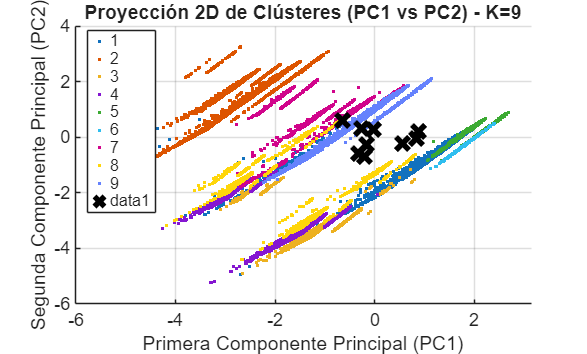



% --- Gráfico 1: Proyección 2D Obligatoria (PC1 vs PC2) ---
% Esta es la visualización más importante para ver la separación de los clústeres.
figure;
gscatter(X_pca(:,1), X_pca(:,2), final_idx);
hold on;
% Proyectar y mostrar los centroides en 2D
plot(final_C(:,1), final_C(:,2), 'kx', 'MarkerSize', 10, 'LineWidth', 3);
hold off;
title(['Proyección 2D de Clústeres (PC1 vs PC2) - K=', num2str(best_k)]);
xlabel('Primera Componente Principal (PC1)');
ylabel('Segunda Componente Principal (PC2)');
legend('show', 'Location', 'bestoutside');
grid on;



% --- Gráfico 2: Vista 3D (Si es posible) ---
if size(X_pca, 2) >= 3
    figure;
    scatter3(X_pca(:,1), X_pca(:,2), X_pca(:,3), 50, final_idx, 'filled');
    hold on;
    % Proyectar centroides 3D
    scatter3(final_C(:,1), final_C(:,2), final_C(:,3), 100, 'kx', 'LineWidth', 3);
    hold off;
    xlabel('PC 1'); ylabel('PC 2'); zlabel('PC 3');
    title(['Clústeres Finales (PCA-KMeans) - K=', num2str(best_k), ' (Vista 3D)']);
    view(3); % Activa la vista 3D
end


output_filename = 'C:/Users/Jesus Coss/Documents/analisis_proyectos/proy_Tarifa_Dinamica/9.DynamicPricing_ETN/9.DynamicPricing_ETN/ClusterKmeansMatlab.xlsx'; % Define el nombre del archivo de salida
sheet_name = 'DatosClusters';                    % Define el nombre de la hoja

% Escribe la tabla en el archivo Excel
writetable(T, output_filename, 'Sheet', sheet_name);


Seleccionando datos